# Transient analysis of one-machine line

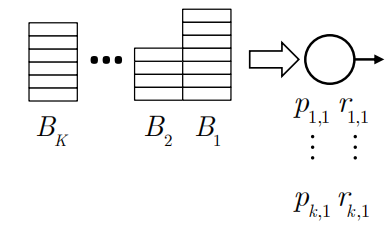

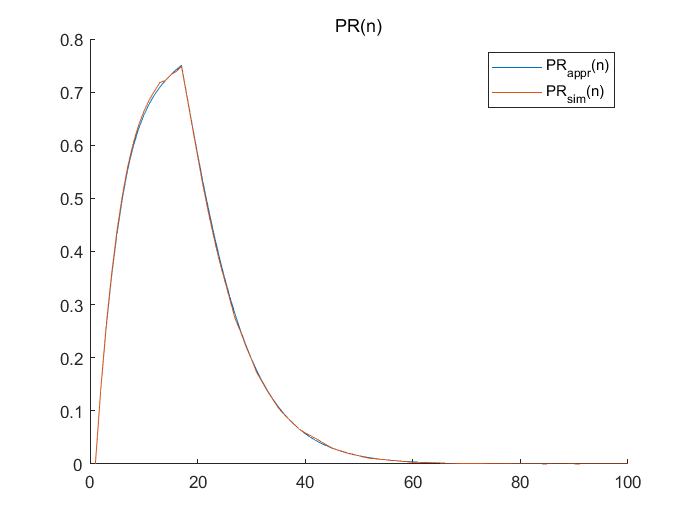

% Set machine parameters
p=[0.03;
   0.06;
   0.05];
r=[0.14;
   0.24;
   0.20];
B=[5 7 4];

% Set inittial state
x_0=[0 0]; % [s, f]
% Run the analysis
T=100;
l=GeometricMultiBatchSingleMachineLine(p, r, B);
% Use the Markov analysis method to get exact analysis results
[PR_appr, ~, ~] = l.markovAnalysis(T,x_0);
% Use the Monte Carlo simulation method
[PR_sim, ~, ~] = l.MonteCarloAnalysis(T,x_0);
% Plot PR(n), the two curves should coincide
figure; hold on;
plot(PR_appr);
plot(PR_sim);
legend('PR_{appr}(n)','PR_{sim}(n)');
title('PR(n)');
hold off;

% E(CT_k) calculation
l.calCTFast(x_0)

ans =    13.0000   21.6250   26.6750


# Transient analysis of two-machine line

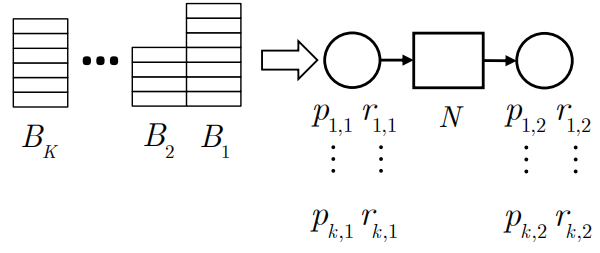

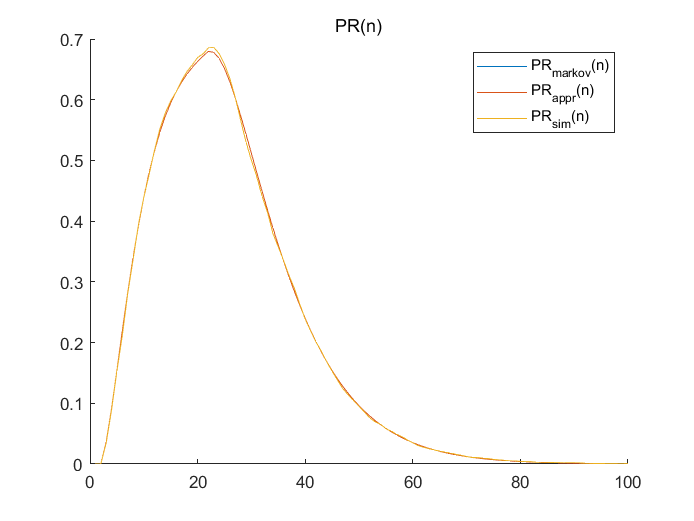

% Set machine parameters
p=[0.03 0.03;
   0.06 0.02];
r=[0.14 0.14;
   0.24 0.16];
B=[10, 10];
n=5;

% Run the analysis
T=100; % evaluation time
l=GeometricMultiBatchDoubleMachineLine(p, r, n, B);
% Use the Markov analysis method to get exact analysis results
[PR_markov, CR_markov, ST_markov, BL_markov, CT_markov] = l.markovAnalysis(T);
% Use the Monte Carlo simulation method
[PR_sim, CR_sim, ~] = l.MonteCarloAnalysis(T);
% Use the approximation method
[PR_appr, CR_appr, ~] = l.approximateAnalysis(T);

% Plot PR(n) and CT(n), the three curves should coincide
figure; hold on;
plot(PR_markov);plot(PR_appr);plot(PR_sim);
legend('PR_{markov}(n)','PR_{appr}(n)','PR_{sim}(n)');
title('PR(n)');
hold off;

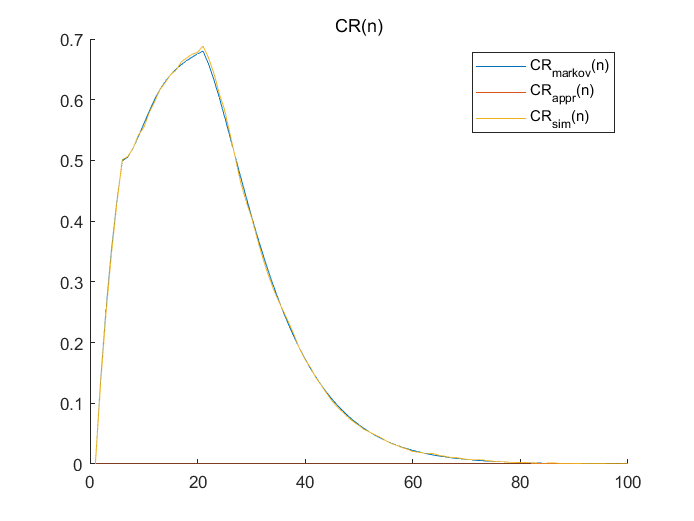

figure; hold on;
plot(CR_markov);plot(CR_appr);plot(CR_sim);
legend('CR_{markov}(n)','CR_{appr}(n)','CR_{sim}(n)');
title('CR(n)');
hold off;


% E(CT)
CT_markov

CT_markov = 38.0695


[CT,PRss] = l.calApprCTUsingSteadyPR()

CT = 27.2347

PRss =     0.7188    0.7506


# Transient analysis of multi-machine line

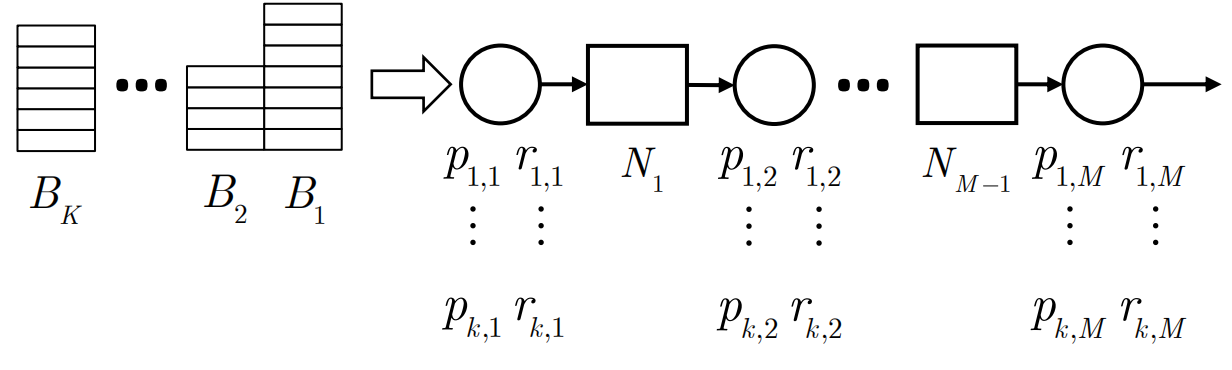

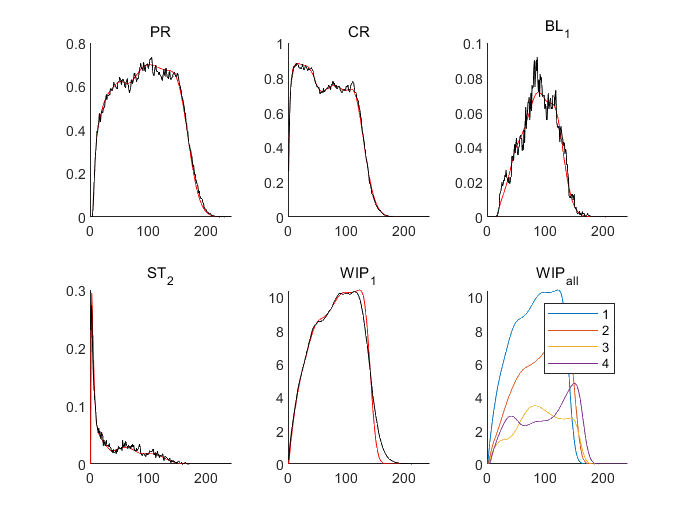

% Generate random line parameters
M=5; % number of machines
B_NUM=10; % number of batches
B_MIN = 7; % minimum batch size
B_MAX = 15; % maximum batch size
R_MIN = 0.2; % minimum repair rate
R_MAX = 0.4; % maximum repair rate
E_MIN = 0.7; % minimum machine efficiency
E_MAX = 0.95; % maximum machine efficiency
N_RANGE_MIN = 2; % minimum buffer size ratio
N_RANGE_MAX = 4; % maximum buffer size ratio

r = unifrnd(R_MIN, R_MAX, B_NUM, M);
e = unifrnd(E_MIN, E_MAX, B_NUM, M);
p = r ./ e - r;
maxMTTR = max(1 ./ r);
N = zeros(1, M - 1);

for m = 1:M - 1
    N(m) = randi([N_RANGE_MIN, N_RANGE_MAX]) * fix(max(maxMTTR(m:m + 1)));
end

B = randi([B_MIN, B_MAX], 1, B_NUM);

% Run the analysis
l = GeometricMultiBatchMultiMachineLine(p, r, N, B);
h_0 = zeros(1, M - 1); % initial buffer occopancy
s_0 = zeros(1, M); % initial machine state
T = 0; % let program determin the evaluation time

[PR_appr, CR_appr, WIP_appr, ST_appr, BL_appr, CT_appr, T_RUN] ...
    = l.approximateAnalysis(T, h_0, s_0, 'Geo');
[PR_sim, CR_sim, WIP_sim, ST_sim, BL_sim, CT_sim] ...
    = l.MonteCarloAnalysis(T_RUN, 1000, h_0, s_0);

% Plot performance metrics
tiledlayout(2,3);
ax = nexttile;
hold(ax, 'on')
title(ax, 'PR');
plot(PR_appr, 'r');
plot(PR_sim, 'k');
hold(ax, 'off');

ax = nexttile;
hold(ax, 'on')
title(ax, 'CR');
plot(CR_appr, 'r');
plot(CR_sim, 'k');
hold(ax, 'off');

ax = nexttile;
hold(ax, 'on')
title(ax, 'BL_1');
plot(BL_appr(1,:), 'r');
plot(BL_sim(1,:), 'k');
hold(ax, 'off');

ax = nexttile;
hold(ax, 'on')
title(ax, 'ST_2');
plot(ST_appr(2,:), 'r');
plot(ST_sim(2,:), 'k');
hold(ax, 'off');

ax = nexttile;
hold(ax, 'on')
title(ax, 'WIP_1');
plot(WIP_appr(1,:), 'r');
plot(WIP_sim(1,:), 'k');
hold(ax, 'off');

ax = nexttile;
hold(ax, 'on')
title(ax, 'WIP_{all}');
for m=1:M-1
    plot(WIP_appr(m,:),'DisplayName',sprintf('%d',m));
end
legend(ax);
hold(ax, 'off');


disp(CT_appr');

   25.6956   44.7771   65.8847   79.8777   99.1190  117.9770  131.0388  146.7647  157.8710  168.6804


disp(CT_sim'); 

   26.1690   44.6860   65.6330   81.0840   99.2580  117.9520  132.6600  149.2010  160.0990  170.4550


### Plot PR(n) with confidence interval

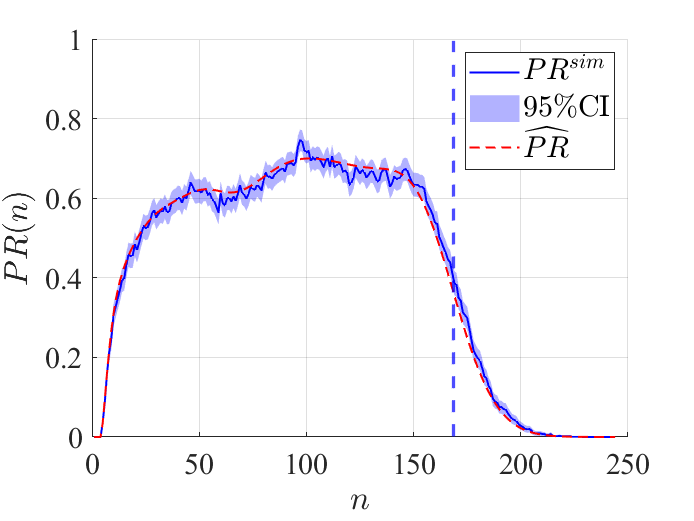

[PR_appr, CR_appr, WIP_appr, ST_appr, BL_appr, CT_appr, T_RUN] ...
    = l.approximateAnalysis(0, h_0, s_0, 'Geo', 1);

N_ITER = 1000;
PRs = zeros(N_ITER, T_RUN);
CRs = zeros(N_ITER, T_RUN);
WIP1s = zeros(N_ITER, T_RUN);
ST2s = zeros(N_ITER, T_RUN);
BL1s = zeros(N_ITER, T_RUN);

% Collect N_ITER simulations
for iITER = 1:N_ITER
    [PR_sim, CR_sim, WIP_sim, ST_sim, BL_sim, CT_sim] ...
        = l.MonteCarloAnalysis(T_RUN, 1, h_0, s_0);
    PRs(iITER, :) = PR_sim;
    CRs(iITER, :) = CR_sim;
    WIP1s(iITER, :) = WIP_sim(1, :);
    ST2s(iITER, :) = ST_sim(end, :);
    BL1s(iITER, :) = BL_sim(1, :);
end

utils.plot_ci(PRs);
fSize = 18;
plot(PR_appr, 'r--', 'LineWidth', 1.2);
xline(CT_appr(end), 'b--', 'LineWidth', 2.0);
ylim([0, 1]);
xlim([0, 250]);
h = legend('$PR^{sim}$', '$95\%$CI', '$\widehat{PR}$');
set(h, 'Interpreter', 'latex', 'FontSize', fSize);
xlabel('$n$', 'Interpreter', 'latex', 'FontSize', fSize);
ylabel('$PR(n)$', 'Interpreter', 'latex', 'FontSize', fSize);
set(gca, 'FontSize', fSize);
set(gca, 'FontName', 'Times');
hold off;

### Approximation of lines with Weibull distribution

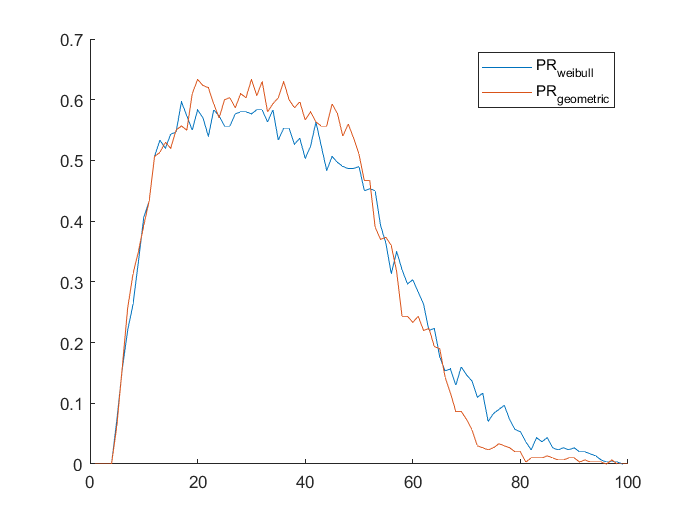

B_NUM = 3; M = 5;
r = unifrnd(0.2, 0.4, B_NUM, M);
e = unifrnd(0.7, 0.95, B_NUM, M);
p = r ./ e - r;
n = ones(1, M - 1) * 7;
B = ones(1, B_NUM) * 10;

T=100; % evaluation time
N_ITER=300; % number of simulation replications
h_0 = zeros(1, M - 1);
s_0 = zeros(1, M);
beta = 0.8;
l = GeometricMultiBatchMultiMachineLine(p, r, n, B);
[PR_webu, CR_webu, WIP_webu, ST_webu, BL_webu, CT_webu]...
    = l.MonteCarloAnalysisNonGeo(T, N_ITER, h_0, s_0, beta);
[PR_geo, CR_geo, WIP_geo, ST_geo, BL_geo, CT_geo]...
    = l.MonteCarloAnalysis(T, N_ITER);
figure; hold on;
plot(PR_webu);
plot(PR_geo);
legend('PR_{weibull}', 'PR_{geometric}');
hold off;

### Approximation versus virtual one-machine lines

M=10; % number of machines
B_NUM=10; % number of batches
B_MIN = 7; % minimum batch size
B_MAX = 15; % maximum batch size
R_MIN = 0.2; % minimum repair rate
R_MAX = 0.4; % maximum repair rate
E_MIN = 0.7; % minimum machine efficiency
E_MAX = 0.95; % maximum machine efficiency
N_RANGE_MIN = 2; % minimum buffer size ratio
N_RANGE_MAX = 4; % maximum buffer size ratio

r = unifrnd(R_MIN, R_MAX, B_NUM, M);
e = unifrnd(E_MIN, E_MAX, B_NUM, M);
p = r ./ e - r;
maxMTTR = max(1 ./ r);
n = zeros(1, M - 1);

for m = 1:M - 1
    n(m) = randi([N_RANGE_MIN, N_RANGE_MAX]) * fix(max(maxMTTR(m:m + 1)));
end

B = randi([B_MIN, B_MAX], 1, B_NUM);
h_0 = zeros(1, M - 1);
s_0 = zeros(1, M);
SIM_T = 0;
line = GeometricMultiBatchMultiMachineLine(p, r, n, B);

tiledlayout(3, 3);
% Type 1: Use Geometric machine as the virtual one-machine line (L_1)
[PR_appr, CR_appr, WIP_appr, ST_appr, BL_appr, CT_appr, T_RUN] ...
    = line.approximateAnalysis(SIM_T, h_0, s_0, 'Geo');
[PR_sim, CR_sim, WIP_sim, ST_sim, BL_sim, CT_sim] ...
    = line.MonteCarloAnalysis(T_RUN, 1000, h_0, s_0);
utils.plot_pr_cr_wip(PR_appr, PR_sim, CR_appr, CR_sim, WIP_appr, WIP_sim, 'Geo');

fprintf('Geo: T_RUN = %.2f; CT_sim = %.2f; CT_appr = %.2f\n', T_RUN, CT_sim(end), CT_appr(end));

Geo: T_RUN = 323.00; CT_sim = 225.28; CT_appr = 221.72



% Type 2: Use Bernoulli machine as the virtual one-machine line (L_1)
[PR_appr, CR_appr, WIP_appr, ST_appr, BL_appr, CT_appr, T_RUN] ...
    = line.approximateAnalysis(T_RUN, h_0, s_0, 'Ber');
utils.plot_pr_cr_wip(PR_appr, PR_sim, CR_appr, CR_sim, WIP_appr, WIP_sim, 'Ber');

fprintf('Ber: T_RUN = %.2f; CT_sim = %.2f; CT_appr = %.2f\n', T_RUN, CT_sim(end), CT_appr(end));

Ber: T_RUN = 323.00; CT_sim = 225.28; CT_appr = 221.17


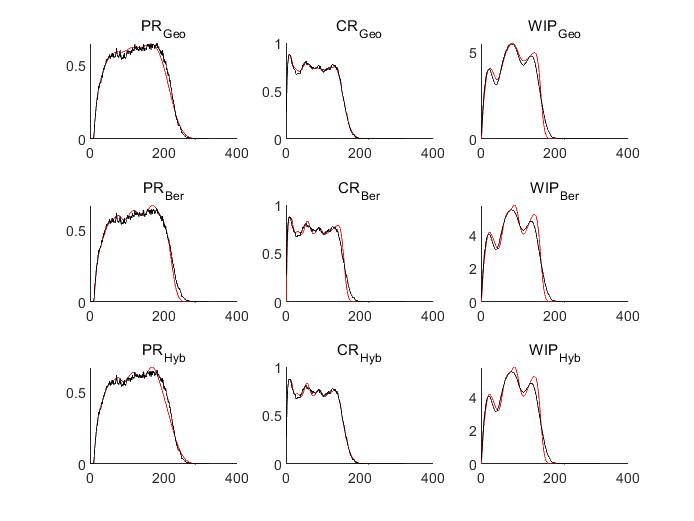


% Type 3: Use both Geometric and Bernoulli machine as the virtual one-machine line (L_1)
[PR_appr, CR_appr, WIP_appr, ST_appr, BL_appr, CT_appr, T_RUN] ...
    = line.approximateAnalysis(T_RUN, h_0, s_0, 'Hyb');
utils.plot_pr_cr_wip(PR_appr, PR_sim, CR_appr, CR_sim, WIP_appr, WIP_sim, 'Hyb');

fprintf('Hyb: T_RUN = %.2f; CT_sim = %.2f; CT_appr = %.2f\n', T_RUN, CT_sim(end), CT_appr(end));

Hyb: T_RUN = 323.00; CT_sim = 225.28; CT_appr = 221.17
